clc % Borra la command window
clear % Limpia las variables del workspace
format short

# Actividades

## A.1) Mostrar la dirección del viento a partir de los datos en *windVectors.csv *

**Set up the Import Options and import the data**

opts = delimitedTextImportOptions("NumVariables", 4);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["longitude", "latitude", "dir", "speed"];
opts.VariableTypes = ["double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
windVectors = readtable("windVectors.csv", opts)

windVectors = 4800×4 table
    longitude    latitude    dir    speed
    _________    ________    ___    _____

      0.125       45.125     228    3.12 
      0.375       45.125     228    3.24 
      0.625       45.125     229    3.34 
      0.875       45.125     229    3.44 
      1.125       45.125     228    3.48 
      1.375       45.125     226    3.49 
      1.625       45.125     225     3.5 
      1.875       45.125     224    3.51 
      2.125       45.125     222    3.52 
      2.375       45.125     220    3.53 
      2.625       45.125     218    3.54 
      2.875       45.125     215    3.55 
      3.125       45.125     208    3.59 
      3.375       45.125     201    3.67 
      3.625       45.125     194     3.8 
      3.875       45.125     190    3.98 


**Clear temporary variables**

clear opts; 

**Visualización**

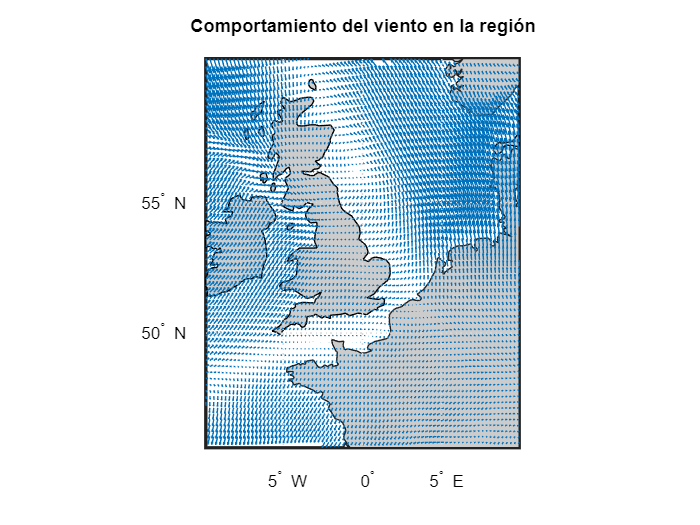

long = windVectors.longitude;
lat = windVectors.latitude;
dir = windVectors.dir;
speed = windVectors.speed;
u = speed .* cosd(dir);
v = speed .* sind(dir);

% Crear un mapa
figure;
hold on;
ax = worldmap([min(lat) max(lat)], [min(long) max(long)]);
setm(ax, 'MapProjection', 'mercator');

% Mostrar mapa base con continentes
geoshow('landareas.shp', 'FaceColor', [0.8 0.8 0.8]);

% Dibujar el campo de viento con flechas
quiverm(lat, long, v, u, 2);

% Etiquetas
title('Comportamiento del viento en la región');
hold off;

## A.2) A partir de la imagen *elevaciones.tif* hacer:

###     1. Mostrar la imagen con 16 tonos de color dependiendo de la elevación.

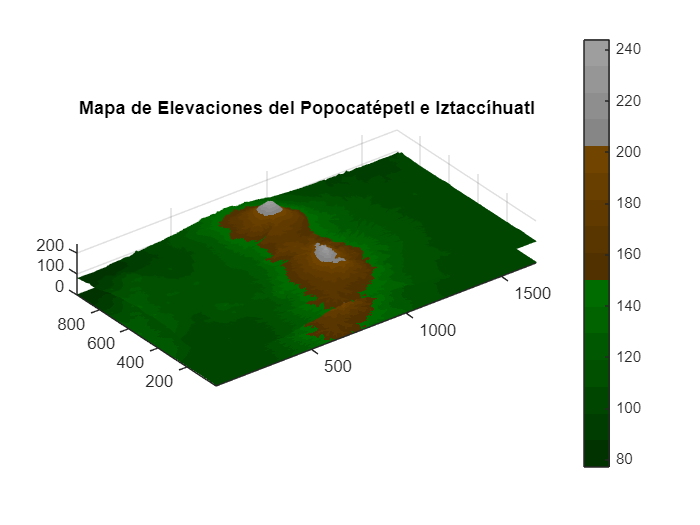

E = imread("elevations.tif");

% Obtener el mínimo y máximo de la matriz E
min_E = double(min(E(:)));
max_E = double(max(E(:)));

% Definir 16 intervalos
num_intervals = 16;
intervals = linspace(min_E, max_E, num_intervals + 1);

% Crear un mapa de colores personalizado en RGB
custom_colormap = zeros(num_intervals, 3); % Inicializar matriz para colores RGB

for i = 1:num_intervals
    % Normalizar el valor del intervalo al rango [0, 1]
    normalized_value = (intervals(i) - min_E) / (max_E - min_E);
    
    % Definir colores para simular la superficie de montaña con mejor degradado
    if normalized_value < 0.4
        % Zonas bajas: verdes oscuros a verdes claros (vegetación)
        green_intensity = 0.2 + 0.6 * normalized_value; % Verde oscuro a verde claro
        custom_colormap(i, :) = [0, green_intensity, 0];
    elseif normalized_value < 0.7
        % Zonas medias: marrones claros a oscuros (rocas y tierra)
        brown_intensity = 0.3 + 0.5 * (normalized_value - 0.4); % Marrón claro a oscuro
        custom_colormap(i, :) = [brown_intensity, brown_intensity * 0.6, 0];
    else
        % Zonas altas: grises a blancos (nieve)
        white_intensity = 0.5 + 0.5 * (normalized_value - 0.7); % Gris a blanco
        custom_colormap(i, :) = [white_intensity, white_intensity, white_intensity];
    end
end

% Generar la grafica
figure;
surf(E) % Mapa de superficie
title('Mapa de Elevaciones del Popocatépetl e Iztaccíhuatl');
hold on
imagesc(E) % Proyeccion del terreno
shading interp;
colormap(custom_colormap);
colorbar;
axis equal;
axis tight;
hold off;

###     2. Realizar una representación de la imagen con curvas de nivel en 2D y 3D.

#### 2D

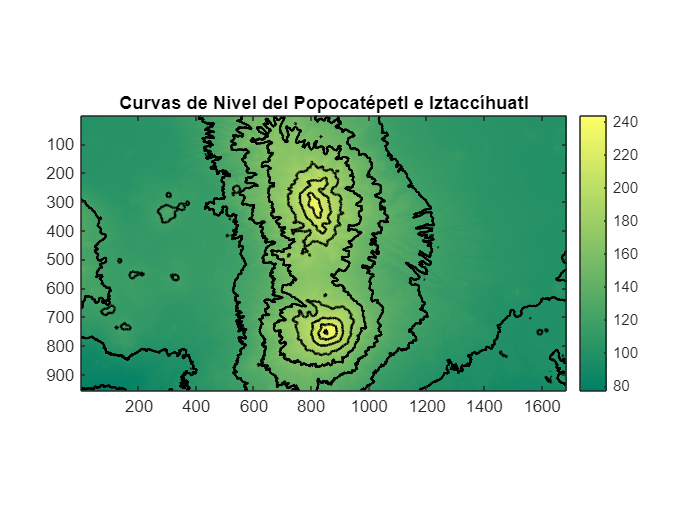

% Mostrar la imagen de fondo con el mapa de colores personalizado
figure;
imagesc(E);
colormap summer;
hold on; % Mantener la figura activa para superponer las curvas de nivel

% Dibujar las curvas de nivel
contour(E, 'LineColor', 'k', 'LineWidth', 1.5);
colorbar;
title('Curvas de Nivel del Popocatépetl e Iztaccíhuatl');
axis equal;
axis tight;
hold off;

#### 3D

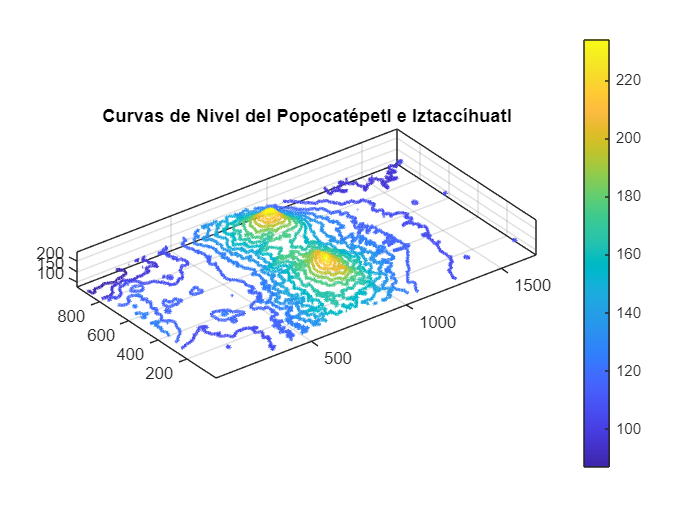

figure;
[M, c] = contour3(E, 16, 'LineWidth', 1.5);
c.LineWidth = 2;
colormap parula;
colorbar;
title('Curvas de Nivel del Popocatépetl e Iztaccíhuatl');
grid on;
axis equal;
axis tight;
view(3);

###     3. Mostrar dos vistas de la superficie representada en el archivo *elevaciones.tif*

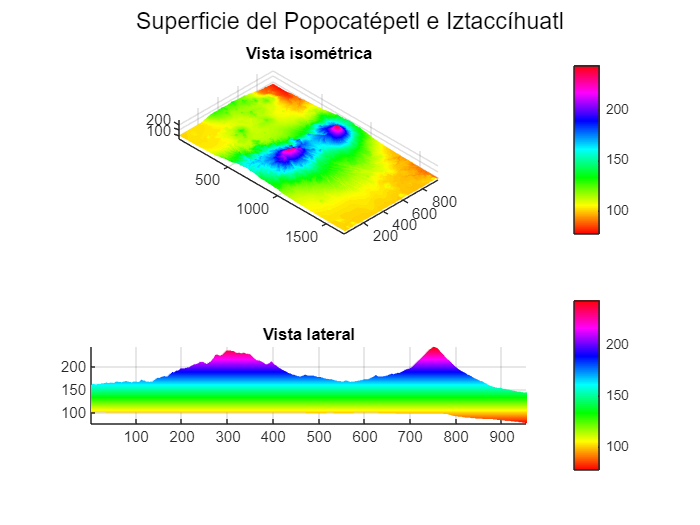

% Crear una figura con dos subgráficos
figure;
sgtitle('Superficie del Popocatépetl e Iztaccíhuatl');

% Primer subgráfico
subplot(2, 1, 1);
surf(E);
shading interp;
colormap hsv;
colorbar;
title('Vista isométrica');
axis equal;
axis tight;
grid on;
view(45, 35.264)
% Segundo subgráfico
subplot(2, 1, 2);
surf(E);
shading interp;
colormap hsv;
colorbar;
title('Vista lateral');
axis equal;
axis tight;
grid on;
view(90, 0);